imds = imageDatastore('Image_data_normalized','IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsTest] = splitEachLabel(imds,0.7,'randomized');
numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure

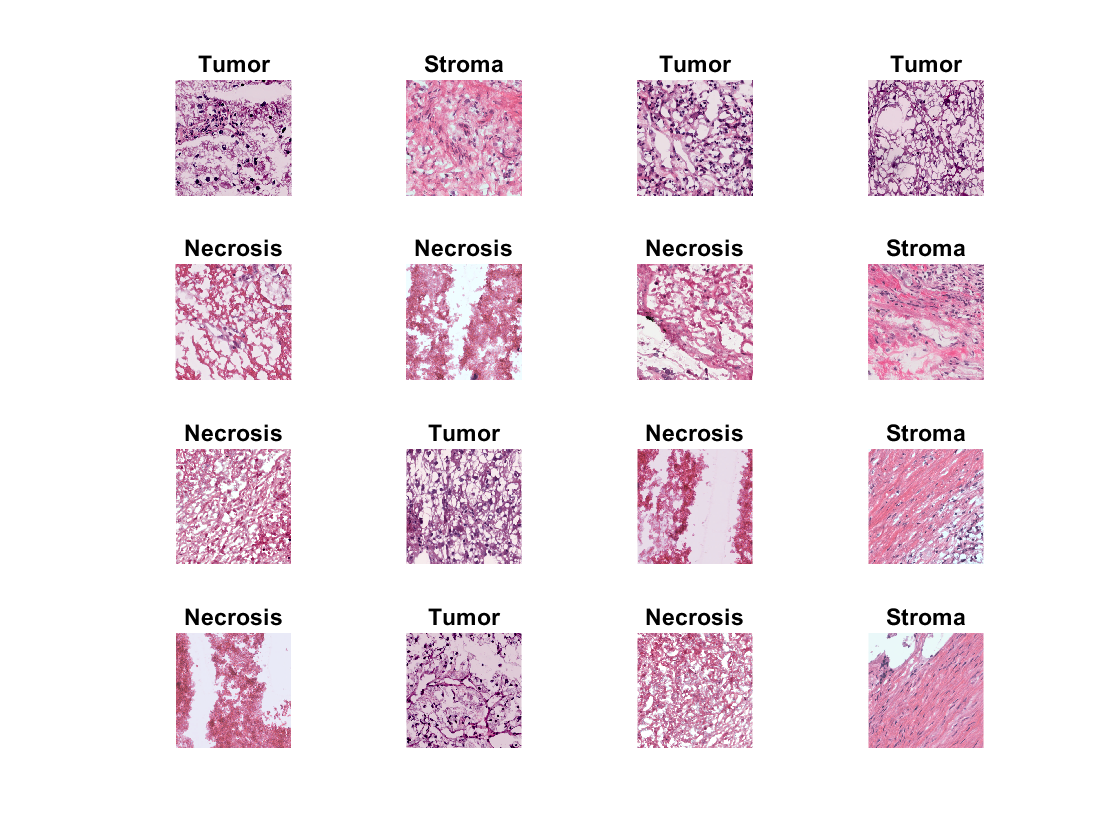


for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    label = imdsTrain.Labels(idx(i));
    imshow(I)
    title(char(label))
end

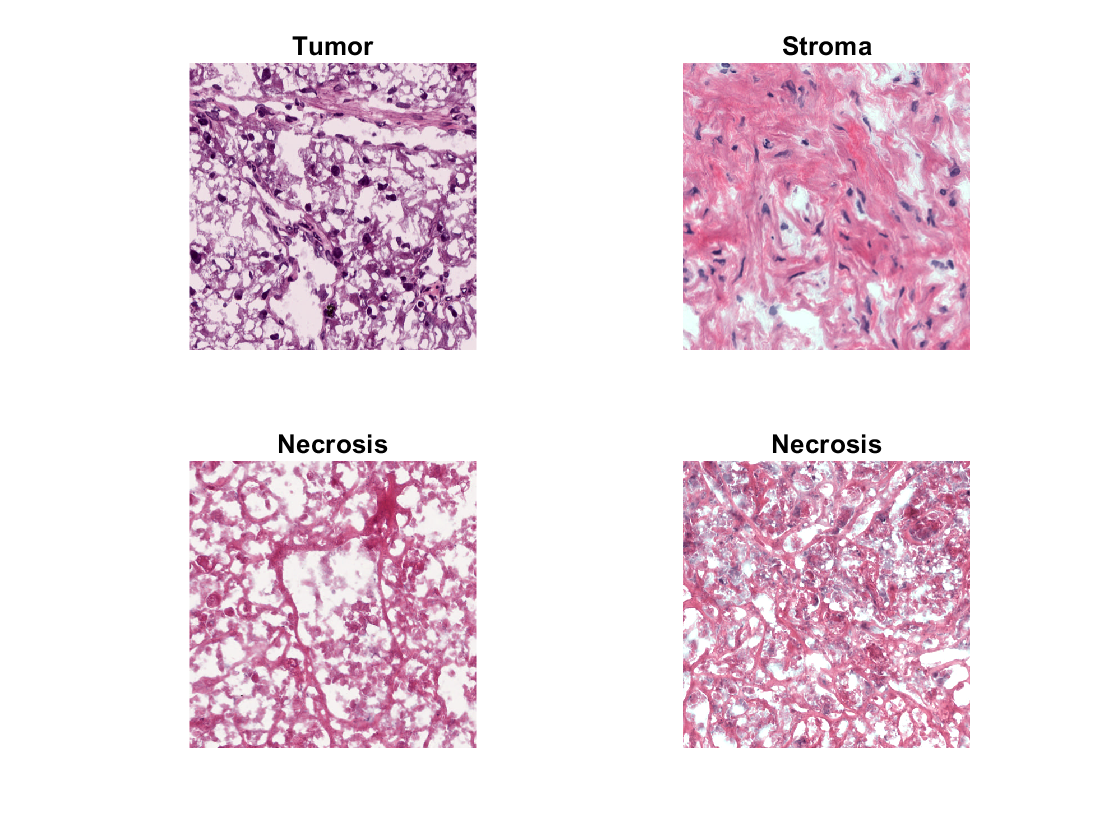


net = resnet18;
inputSize = net.Layers(1).InputSize;
%analyzeNetwork(net)
audimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);
layer = 'pool5';
featuresTrain = activations(net,audimdsTrain,layer,'OutputAs','rows');
featuresTest = activations(net,augimdsTest,layer,'OutputAs','rows');
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;
classifier = fitcecoc(featuresTrain,YTrain);
YPred = predict(classifier,featuresTest);
numTestImages = numel(YTest);
idx = randperm(numTestImages,4);
figure
for i = 1:numel(idx)
    subplot(2,2,i)
    I = readimage(imdsTest,idx(i));
    label = YPred(idx(i));
    imshow(I)
    title(char(label))
end